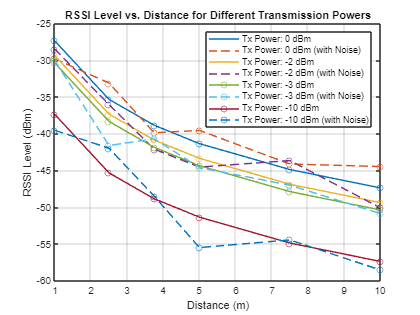

clc;
clear;
close all;

distances = [1, 2.5, 3.75, 5, 7.5, 10]; % Distances in meters
txPowers = [0, -2, -3, -10]; % Transmission powers in dBm

% Initialize figure for RSSI vs. Distance plot
figure;

% Loop over transmission powers
for i = 1:length(txPowers)
    rssiValues = calculateRSSI(distances, txPowers(i)); % Calculate RSSI values for the specific transmission power
    
    % Add noise to the RSSI values
    rssiValuesWithNoise = addNoise(rssiValues);
    
    % Plot RSSI vs. Distance for the current transmission power with and without noise
    plot(distances, rssiValues, 'o-', 'DisplayName', sprintf('Tx Power: %d dBm', txPowers(i)));
    hold on;
    plot(distances, rssiValuesWithNoise, 'o--', 'DisplayName', sprintf('Tx Power: %d dBm (with Noise)', txPowers(i)));
end

hold off;
xlabel('Distance (m)');
ylabel('RSSI Level (dBm)');
title('RSSI Level vs. Distance for Different Transmission Powers');
legend('Location', 'northeast');
grid on;


% Create table for RSSI values
tableData = table(distances', 'VariableNames', {'Distance'});
txPowerLabels = cellstr(num2str(txPowers', 'Tx Power: %d dBm'));
for i = 1:length(txPowers)
    rssiColName = strcat('RSSI (', txPowerLabels{i}, ')');
    rssiWithNoiseColName = strcat('RSSI with Noise (', txPowerLabels{i}, ')');
    tableData = addvars(tableData, calculateRSSI(distances, txPowers(i))', addNoise(rssiValues)', 'NewVariableNames', {rssiColName, rssiWithNoiseColName});
end

% Display the table
disp(tableData);

    Distance    RSSI (  Tx Power: 0 dBm)    RSSI with Noise (  Tx Power: 0 dBm)    RSSI ( Tx Power: -2 dBm)    RSSI with Noise ( Tx Power: -2 dBm)    RSSI ( Tx Power: -3 dBm)    RSSI with Noise ( Tx Power: -3 dBm)    RSSI (Tx Power: -10 dBm)    RSSI with Noise (Tx Power: -10 dBm)
    ________    ________________________    ___________________________________    ________________________    ___________________________________    ________________________    ___________________________________    ________________________    ___________________________________

         1                -27.4                           -37.364                            -29.4                            -33.5

function rssiValues = calculateRSSI(distances, txPower)
    % Calculate RSSI values based on distances and transmission power
    
    % Constants for RSSI calculation (you can modify these as needed)
    referenceDistance = 1; % Reference distance in meters
    referenceRSSI = -30; % RSSI level at reference distance
    pathLossExponent = 2.6; % Path loss exponent
    
    % Preallocate array for RSSI values
    rssiValues = zeros(size(distances));
    
    % Loop over distances
    for j = 1:length(distances)
        % Calculate path loss using the path loss exponent
        pathLoss = 20 * log10(distances(j) / referenceDistance);
        
        % Calculate RSSI level using reference RSSI, path loss, and path loss exponent
        rssi = referenceRSSI - pathLoss + pathLossExponent;
        
        % Adjust RSSI level based on transmit power
        rssi = rssi + txPower;
        
        % Store RSSI value in the array
        rssiValues(j) = rssi;
    end
end

function rssiValuesWithNoise = addNoise(rssiValues)
    % Add noise to the RSSI values
    
    % Constants for noise calculation (you can modify these as needed)
    noisePower = 2; % Noise power in dBm
    
    % Generate random noise with the same size as the input RSSI values
    noise = noisePower * randn(size(rssiValues));
    
    % Add noise to the RSSI values
    rssiValuesWithNoise = rssiValues + noise;
end
